# 1.2.09. Загрузка, обработка и визуализация экспериментальных данных

**Практическое занятие**

## Импорт из Excel

В файле `students.xlsx` хранятся оценки студентов по самостоятельным работам. Считайте их виде таблицы (`table`) в переменную `G` (подсказка: `readtable()`)

G = readtable('students.xlsx')

G = 7×4 table
          x___           x______1    x______2    x______3
    _________________    ________    ________    ________

    'Ботанин Илья'           3           2           2   
    'Ботанин Пётр'         NaN         NaN           5   
    'Дрёмин Иван'            4           5           5   
    'Дубинин Дмитрий'        5           2           4   
    'Рословец Павел'         3           3           5   
    'Старостин Олег'         5           5           5   
    'Фелонин Антон'        NaN         NaN         NaN   


Заголовки столбцов в файле подписаны по-русски, поэтому они считались некорректно. Измените в таблице `G` подписи столбцов на:

G.Properties.VariableNames = {'Name', 'W1', 'W2', 'W3'}

G = 7×4 table
          Name           W1     W2     W3 
    _________________    ___    ___    ___

    'Ботанин Илья'         3      2      2
    'Ботанин Пётр'       NaN    NaN      5
    'Дрёмин Иван'          4      5      5
    'Дубинин Дмитрий'      5      2      4
    'Рословец Павел'       3      3      5
    'Старостин Олег'       5      5      5
    'Фелонин Антон'      NaN    NaN    NaN


## Импорт из текстовых файлов

В файле `signal.txt` лежит записанный в ходе лабораторной работы сигнал. Хранится он в виде таблицы из двух столбцов - `Time` и `Signal`. Значения в строках разделены запятыми. Откройте этот файл в текстовом редакторе (MATLAB Editor) и изучите его структуру.

При помощи функции `readtable()` считайте сигнал из файла `signal.txt` в переменную `S`

S = readtable('signal.txt')

S = 1001×3 table
         Var1          Var2              Var3           
    _______________    ____    _________________________

    '12.09.2018 12'     52     '00.0,0.7376671395461'   
    '12.09.2018 12'     52     '00.1,2.0429849402786'   
    '12.09.2018 12'     52     '00.2,-2.04064745553115' 
    '12.09.2018 12'     52     '00.3,1.08947131386236'  
    '12.09.2018 12'     52     '00.4,0.555160483778756' 
    '12.09.2018 12'     52     '00.5,-1.06219758531964' 
    '12.09.2018 12'     52     '00.6,-0.179008073289921'
    '12.09.2018 12'     52     '00.7,0.606298978981957' 
    '12.09.2018 12'     52     '00.8,3.85115889555824'  
    '12.09.2018 12'     52     '00.9,3.05128286378526'  
    '12.09.2018 12'     52     '01.0,-1.05896123861773' 
    '12.09.2018 12'     52     '01.1,3.33492458016788'  
    '12.09.2018 12'     52     '01.2,1.03447585104479'  
    '12.09.2018 12'     5

Обратите внимание, что данные считались из файла некорректно из-за особого формата записи временных меток в столбце `Time`. Судя по всему, MATLAB использовал в качестве разделителей данных символы `,` и `:`. Такое поведение можно исправить, если вручную указать при импорте разделитель (`,`). Сделать это можно дополнительным аргументом функции `readtable` - '`Delimiter'`.

Импортируйте данные правильно, указав разделитель, в переменную `S`

S = readtable('signal.txt', 'Delimiter', ',')

S = 1001×2 table
             Time               Signal 
    _______________________    ________

    '12.09.2018 12:52:00.0'     0.73767
    '12.09.2018 12:52:00.1'       2.043
    '12.09.2018 12:52:00.2'     -2.0406
    '12.09.2018 12:52:00.3'      1.0895
    '12.09.2018 12:52:00.4'     0.55516
    '12.09.2018 12:52:00.5'     -1.0622
    '12.09.2018 12:52:00.6'    -0.17901
    '12.09.2018 12:52:00.7'      0.6063
    '12.09.2018 12:52:00.8'      3.8512
    '12.09.2018 12:52:00.9'      3.0513
    '12.09.2018 12:52:01.0'      -1.059
    '12.09.2018 12:52:01.1'      3.3349
    '12.09.2018 12:52:01.2'      1.0345
    '12.09.2018 12:52:01.3'     0.25508
    '12.09.2018 12:52:01.4'      1.0419
    '12.09.2018 12:52:01.5'     0.13128


Из-за особого формата записи времени, столбец `Time` импортировался как обычный текст (`cell string`), работать с такими временными метками при анализе неудобно. Сконвертируйте столбец `Time` в формат `datetime` (подсказка: `datetime()`)

S.Time = datetime(S.Time)

S = 1001×2 table
            Time             Signal 
    ____________________    ________

    12-Sep-2018 12:52:00     0.73767
    12-Sep-2018 12:52:00       2.043
    12-Sep-2018 12:52:00     -2.0406
    12-Sep-2018 12:52:00      1.0895
    12-Sep-2018 12:52:00     0.55516
    12-Sep-2018 12:52:00     -1.0622
    12-Sep-2018 12:52:00    -0.17901
    12-Sep-2018 12:52:00      0.6063
    12-Sep-2018 12:52:00      3.8512
    12-Sep-2018 12:52:00      3.0513
    12-Sep-2018 12:52:01      -1.059
    12-Sep-2018 12:52:01      3.3349
    12-Sep-2018 12:52:01      1.0345
    12-Sep-2018 12:52:01     0.25508
    12-Sep-2018 12:52:01      1.0419
    12-Sep-2018 12:52:01     0.13128


После импорта данных, хочется на них взглянуть. Выведите первые 8 строк и заголовки таблицы `S` с помощью функции `head()`

head(S)

ans = 8×2 table
            Time             Signal 
    ____________________    ________

    12-Sep-2018 12:52:00     0.73767
    12-Sep-2018 12:52:00       2.043
    12-Sep-2018 12:52:00     -2.0406
    12-Sep-2018 12:52:00      1.0895
    12-Sep-2018 12:52:00     0.55516
    12-Sep-2018 12:52:00     -1.0622
    12-Sep-2018 12:52:00    -0.17901
    12-Sep-2018 12:52:00      0.6063


Выведите сводную информацию о таблице `S` с помощью функции `summary()`

summary(S)


Variables:

    Time: 1001×1 datetime

        Values:

            Min       12-Sep-2018 12:52:00
            Median    12-Sep-2018 12:52:50
            Max       12-Sep-2018 12:53:40

    Signal: 1001×1 double

        Values:

            Min            -3.4548 
            Median         0.1986  
            Max            4.4203  
            NumMissing     44      



## Чтение текста из файлов

Иногда нужно просто считать текст из неструктурированного файла.

С помощью функции `fileread() `считайте весь текст из файла `info.txt` в переменную `info`

info = fileread('info.txt')

info =     'MATLAB отлично подходит для обучения студентов, начиная от теоретических основ базовых дисциплин, заканчивая профессиональными практическими навыками.
     Поэтому вы его сейчас и изучаете.'


Команда `type` позволяет просто вывести текстовое содержимое файла на экран. Сделайте это

type info.txt


MATLAB отлично подходит для обучения студентов, начиная от теоретических основ базовых дисциплин, заканчивая профессиональными практическими навыками.
Поэтому вы его сейчас и изучаете.


## Импорт изображений

Считайте с диска изображение `MATLAB-logo.jpg` с помощью функции `imread` в переменную `img`

img = imread('MATLAB-logo.jpg')

img = 564×614×3 uint8 array
img(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   2

Обратите внимание, что изображение хранится в памяти как матрица размерностью `564x614x3 `формата `uint8`. Каждый элемент матрицы - это яркость пикселя соответствующего цвета (Red, Green, Blue)

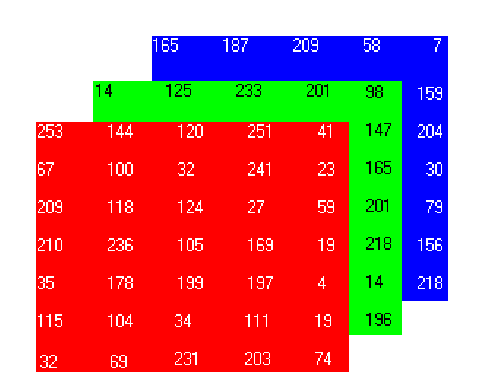

Выведите изображение `img` на экран с помощью функции `imshow()`

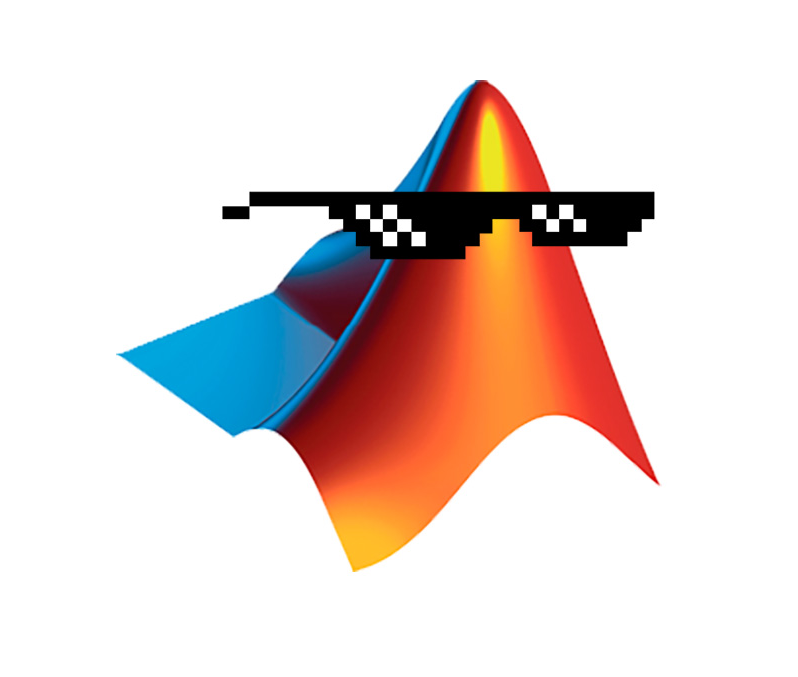

imshow(img)

## Получение данных из интернета

С помощью функции `webread()` считайте по адресу `'https://restcountries.eu/rest/v2/region/europe'` информацию о европейских странах в переменную `data`

data = webread('https://restcountries.eu/rest/v2/region/europe')

data = 53×1 struct array with fields:
    name
    topLevelDomain
    alpha2Code
    alpha3Code
    callingCodes
    capital
    altSpellings
    region
    subregion
    population
    latlng
    demonym
    area
    gini
    timezones
    borders
    nativeName
    numericCode
    currencies
    languages
    translations
    flag
    regionalBlocs
    cioc


По умолчанию данные считываются в массив структур (`structure array`). Конвертируйте переменную `data` в таблицу (`table`) (подсказка: `struct2table()`)

data = struct2table(data)

data = 53×24 table
              name              topLevelDomain    alpha2Code    alpha3Code    callingCodes         capital          altSpellings     region         subregion        population       latlng               demonym               area        gini        timezones      borders           nativeName          numericCode     currencies      languages      translations                     flag                      regionalBlocs    cioc 
    ________________________    ______________    __________    __________

*2018 © ЦИТМ Экспонента*